%Nodes = Nodes'; 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind = zeros(4,10000);
for i=1:length(Nodes)
    for k=0:99999
        if Nodes(i,1) <= 18500+k && Nodes(i,2)>18500+k
            ind(Nodes(i,3),k+1)=ind(Nodes(i,3),k+1)+1;
        end
    end
end        

Index exceeds matrix dimensions.

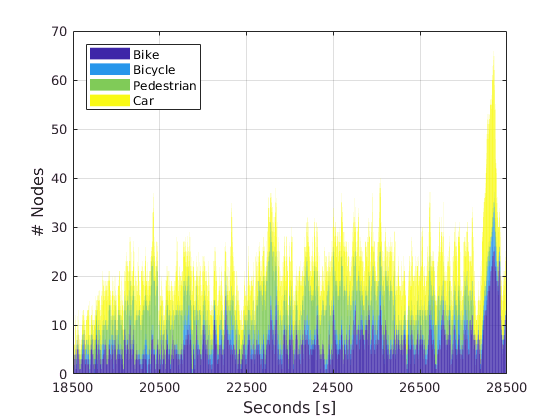

figure (4)
bar(ind','stacked')
title('')
%ylim([0, 1.1])
xticklabels([18500 20500 22500 24500 26500 28500])
xlabel('Seconds [s]','FontSize',12);
ylabel('# Nodes','FontSize',12);
legend('Bike','Bicycle','Pedestrian','Car','Location','NorthWest');
grid on
xlim([0,10000])

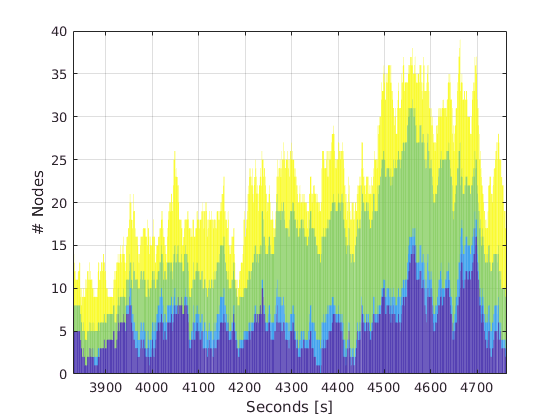


figure (2)
bar(ind','stacked')
title('')
%ylim([0, 1.1])
%xticklabels([18500 22500 24500 26500 28500])
xlabel('Seconds [s]');
ylabel('# Nodes');
%legend('Bike','Bicycle','Pedestrian','car','Location','NorthWest');
grid on
%xlim([0,10000])
xlim([3829 4764])

% fila 1: Bikenode -> 1
% fila 2: Bicyclenode -> 2
% fila 3: Pednode -> 3
% fila 4: Car -> 4 

z =sum(ind);
st=[18000 18000 18000 18000];

st =        18000       18000       18000       18000



figure (3)
%S1
h1 = subplot(2,2,1);
bar(ind','stacked')
title('')
%ylim([0, 1.1])


%xticklabels([219 219 219 219])
xlabel('');
ylabel('# Nodes');
legend('Bike','Bicycle','Pedestrian','car','Location','NorthWest');
grid on
xlim([3905 3912])
ylim([0 45])
ind(:,3905:3912)

ans =      4     4     4     4     4     4     4     4
     0     0     0     0     0     0     0     0
     3     3     3     3     3     3     3     3
     2     2     2     2     2     2     2     2


z(:,3905:3912)

ans =      9     9     9     9     9     9     9     9



st1=st + [3906 3908 3910 3912];
title(h1,'Scenario 1');
set(h1,'XTickLabel',{st1});

h2 = subplot(2,2,2);
% S2
bar(ind','stacked')
title('')
%ylim([0, 1.1])
%xticklabels([18500 22500 24500 26500 28500])
xlabel('');
ylabel('');
%legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
grid on
xlim([4035 4042])
ylim([0 45])
ind(:,4035:4042)

ans =      6     6     6     6     6     6     7     7
     2     2     2     2     2     2     2     2
     5     5     5     5     5     4     4     4
     6     6     7     7     7     7     8     8


z(:,4035:4042)

ans =     19    19    20    20    20    19    21    21



st1=st + [4036 4038 4040 4042];
title(h2,'Scenario 2');
set(h2,'XTickLabel',{st1});

h3 = subplot(2,2,3);
% S3
bar(ind','stacked')
title('')
%ylim([0, 1.1])
%xticklabels([18500 22500 24500 26500 28500])
xlabel('Seconds [s]');
ylabel('# Nodes');
%legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
grid on
xlim([4384 4391])
ylim([0 45])
ind(:,4384:4391)

ans =      5     5     5     6     6     7     7     7
     3     3     3     3     3     2     2     1
    11    11    11    11    11    11    12    12
     7     7     8     8     8     8     8     8


z(:,4384:4391)

ans =     26    26    27    28    28    28    29    28



st1=st + [4384 4386 4388 4390];
title(h3,'Scenario 3');
set(h3,'XTickLabel',{st1});

h4 = subplot(2,2,4);

% S4
ind(:,4553:4560)

ans =     12    13    13    13    14    14    14    15
     3     3     3     3     2     2     2     2
    15    15    15    15    15    15    15    15
     5     5     5     6     6     6     5     6


z(:,4553:4560)

ans =     35    36    36    37    37    37    36    38


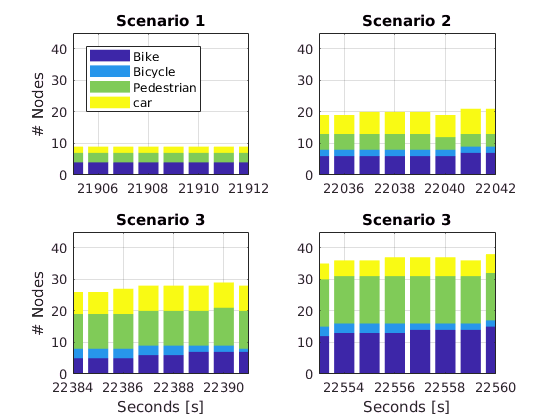

bar(ind','stacked')
title('')
%ylim([0, 1.1])
%xticklabels([18500 22500 24500 26500 28500])
xlabel('Seconds [s]');
ylabel('');
%legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
grid on
xlim([4553 4560])
ylim([0 45])

st1=st + [4554 4556 4558 4560];
title(h4,'Scenario 3');
set(h4,'XTickLabel',{st1});